L(1) = Link('revolute','alpha',pi/2,'a',0,'d',40,'offset',0,'qlim',[-3*pi/4 3*pi/4]);
L(2) = Link('revolute','alpha',0,'a',-110,'d',0,'offset',-pi/2,'qlim',[-3*pi/4 3*pi/4]);
L(3) = Link('revolute','alpha',0,'a',110,'d',0,'offset',pi/2,'qlim',[-3*pi/4 3*pi/4]);
L(4) = Link('revolute','alpha',pi/2,'a',90,'d',0,'offset',0,'qlim',[-3*pi/4 3*pi/4]);
Robot = SerialLink(L,'name','Px')

 
Robot = 
 
Px (4 axis, RRRR, stdDH, slowRNE)                                
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         40|          0|      1.571|          0|
|  2|         q2|          0|       -110|          0|     -1.571|
|  3|         q3|          0|        110|          0|      1.571|
|  4|         q4|          0|         90|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1            

Robot.tool=[0 0 1 0;
            0 1 0 0;
            -1 0 0 0;
            0 0 0 1];
q1=[0 0 0 0];
Hbt1=L(1).A(q1(1))*L(2).A(q1(2))*L(3).A(q1(3))*L(4).A(q1(4))

Hbt1 =     1.0000         0         0  200.0000
         0   -1.0000   -0.0000    0.0000
         0    0.0000   -1.0000  150.0000
         0         0         0    1.0000


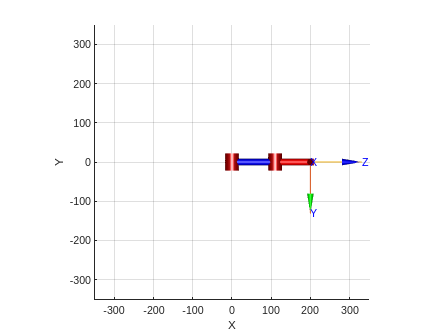

Robot.plot(q1,'notiles','noname');

HOME=[0 0 pi/2 0];
Hbt2=L(1).A(HOME(1))*L(2).A(HOME(2))*L(3).A(HOME(3))*L(4).A(HOME(4))

Hbt2 =     0.0000   -0.0000    1.0000    0.0000
    0.0000   -1.0000   -0.0000    0.0000
    1.0000    0.0000   -0.0000  350.0000
         0         0         0    1.0000


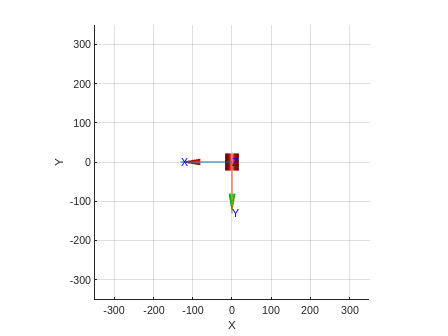

Robot.plot(HOME,'notiles','noname');

GOAL=[3*pi/8 3*pi/8 7*pi/8 3*pi/8];
Hbt3=L(1).A(GOAL(1))*L(2).A(GOAL(2))*L(3).A(GOAL(3))*L(4).A(GOAL(4))

Hbt3 =     0.1464    0.9239   -0.3536  -55.4765
    0.3536   -0.3827   -0.8536 -133.9320
   -0.9239    0.0000   -0.3827  -78.8357
         0         0         0    1.0000


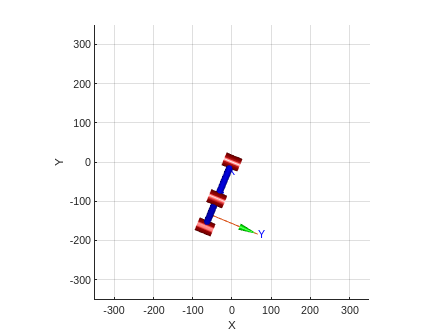

Robot.plot(GOAL,'notiles','noname');

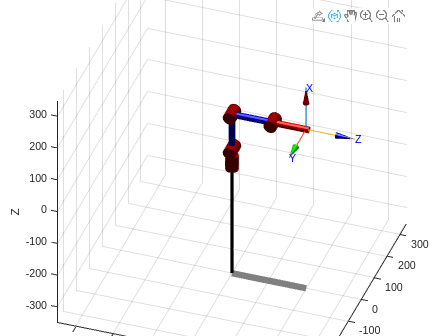

q1=[0 0 0 0];
Robot.plot(q1,'notiles','noname')

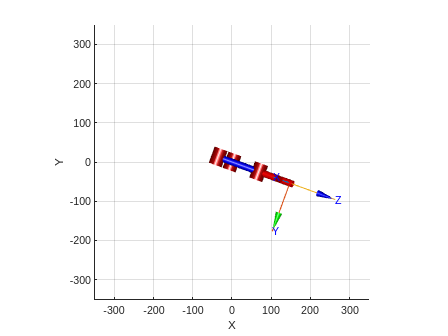

q2=[-20*pi/180, 20*pi/180, -20*pi/180, 20*pi/180];
Robot.plot(q2,'notiles','noname')

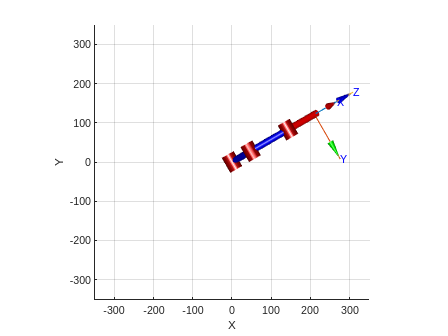

q3=[30*pi/180, -30*pi/180, 30*pi/180, -30*pi/180];
Robot.plot(q3,'notiles','noname')

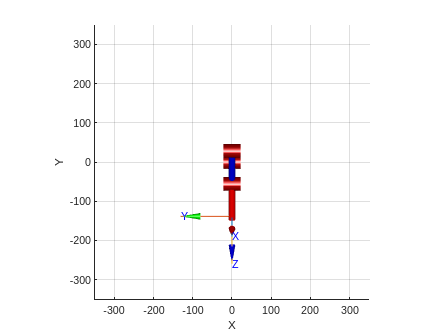

q4=[-pi/2,15*pi/180,-55*pi/180,17*pi/180];
Robot.plot(q4,'notiles','noname')

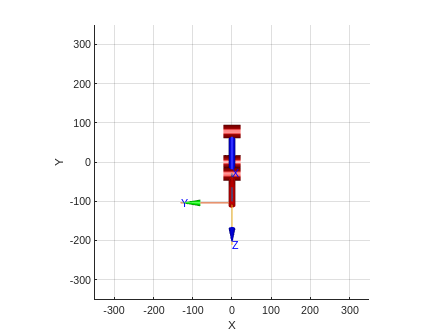

q5=[-pi/2,pi/4,-55*pi/180,pi/4];
Robot.plot(q5,'notiles','noname')